load uspsDigits.mat;
% fix so is uses the centroid of the training data and check vs the test
% data
% reshape(trainDigits, [256, 1, 7291]);

% centroid metoden (mot 1 centroid - typ värdelös)
% fix loop and check tempDiff
%ima(testDigits(:,:,1))
randImgIndex = randi(2007)

randImgIndex = 1636


indexDigit = find(testAns == 4);

%mean(testDigits(indexDigit),3)
sumDigit = zeros(16,16,1);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,1) = sumDigit(:,:,1) + testDigits(:,:,indexValue);
end
meanDigit = sumDigit./length(indexDigit);
ima(testDigits(:,:,randImgIndex))
ima(meanDigit)


testAns(randImgIndex)

ans = 1

%tempDiff = abs(norm(meanDigit(:,:,1)) - norm(testDigits(:,:,randImgIndex)))
tempDiff = abs(norm(meanDigit(:,:,1) - testDigits(:,:,randImgIndex))) % this is the right one?

tempDiff = 5.0777

% centroid metoden
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1270

results = zeros(10,1);
sumDigit = zeros(16,16,10);
for dig = 0:9
    indexDigit = find(trainAns == dig);
    
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        trainDigits(:,:,indexValue);
        sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + trainDigits(:,:,indexValue);
    end
    meanDigit = sumDigit./length(indexDigit);
    tempDiff = abs(norm(meanDigit(:,:,dig + 1) - testDigits(:,:,randImgIndex)));
    results(dig + 1) = tempDiff;
end
results

results =     6.3895
    1.8136
    4.9375
    5.2022
    4.5421
    5.0449
    4.8421
    4.4362
    5.1184
    4.5535


[M,I] = min(results);
minDigit = I-1

minDigit = 1

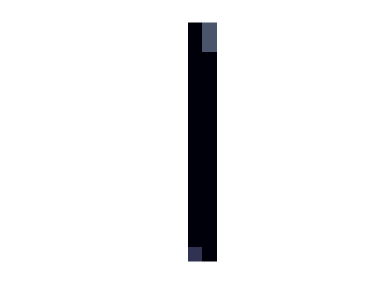

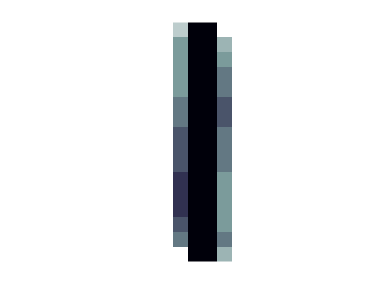

ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))

% ladda centroider i centroidDigit
disp('new part')

new part


centroidDigit = zeros(16,16,10);
for digit = 0:9
    indexDigit = find(trainAns == digit);
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        centroidDigit(:,:,digit + 1) = centroidDigit(:,:,digit + 1) + trainDigits(:,:,indexValue);
    end
    centroidDigit(:,:,digit + 1) = centroidDigit(:,:,digit + 1)./length(indexDigit);
end

centroidResults = zeros(length(testAns), 2);
centroidResults(:, 1) = testAns;

for currentIndex = 1:length(testAns)

    currentResult = zeros(10,1);

    for digit = 0:9
        currentResult(digit + 1) = abs(norm(centroidDigit(:,:,digit + 1) - testDigits(:,:,currentIndex)));
    end
    currentResult;
    [~,I] = min(currentResult);
    centroidResults(currentIndex,2) = I-1;
end
centroidResults

centroidResults =      9     9
     6     2
     3     3
     6     2
     6     0
     0     0
     0     0
     0     0
     6     6
     9     9


amountWrong = zeros(10,1);

for digit = 0:9
    allOfDigit = find(centroidResults(:,1) == digit);
    for index = 1:length(allOfDigit)
        indexOfCurrent = allOfDigit(index);
        if centroidResults(indexOfCurrent,1) ~= centroidResults(indexOfCurrent,2)
            amountWrong(digit + 1) = amountWrong(digit + 1) + 1;
        end
    end
end

amountWrong

amountWrong =     63
    12
    63
    50
    58
    53
    33
    29
    52
    35


% closest neighbooooor
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 255

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;
for c = 1:2007
    if c ~= randImgIndex
        %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
        tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            savedIndex = c;
        end
    end
end 
savedIndex

savedIndex = 899

savedDiff

savedDiff = 5.8168

testAns(randImgIndex)

ans = 8

testAns(savedIndex)

ans = 8

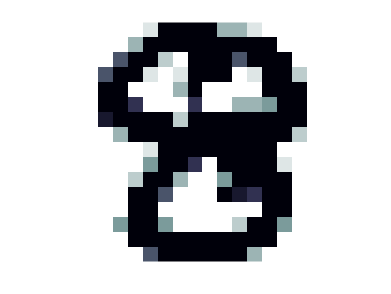

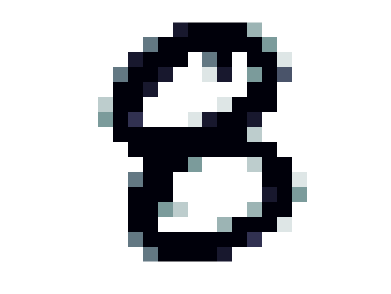

ima(testDigits(:,:,randImgIndex))
ima(testDigits(:,:,savedIndex))

% 5 closest neighbooors 
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1834

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;

nClosesNeighbooorIndex = [0;0;0;0;0];
nClosesNeighbooorValues = [savedDiff;savedDiff;savedDiff;savedDiff;savedDiff];

for n = 1:5
    for c = 1:2007
        if c ~= randImgIndex && c ~= nClosesNeighbooorIndex(1) && c ~= nClosesNeighbooorIndex(2) && c ~= nClosesNeighbooorIndex(3) && c ~= nClosesNeighbooorIndex(4) && c ~= nClosesNeighbooorIndex(5)
            %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
            tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));

            for j = 1:5
                if tempDiff < nClosesNeighbooorValues(j)
                    nClosesNeighbooorValues(j) = tempDiff;
                    nClosesNeighbooorIndex(j) = c;
                    break;
                end
            end
        end
    end 
end

nClosesNeighbooorIndex

nClosesNeighbooorIndex =         1824
        1598
        1651
        1215
        1201


testAns(nClosesNeighbooorIndex)

ans =      1
     1
     1
     1
     1


disp(['The most common number is (multiple values occurring equally frequently, ' newline 'mode returns the smallest of those values):'])

The most common number is (multiple values occurring equally frequently, 
mode returns the smallest of those values):


mode(testAns(nClosesNeighbooorIndex))

ans = 1

nClosesNeighbooorValues

nClosesNeighbooorValues =     0.7673
    0.7769
    0.8034
    0.8385
    0.9067


testAns(randImgIndex)

ans = 1

% first closest neighbooors 
disp('new part')

new part



%kolTrainDigits = reshape(trainDigits, [256, 1, 7291]);
neighboorResults = zeros(length(testAns), 2);
neighboorResults(:, 1) = testAns;


for testIndex = 1:length(testAns)
    savedIndex = 0;
    savedDiff = 1e3;
    for trainIndex = 1:length(trainAns)
        tempDiff = abs(norm(testDigits(:,:,testIndex) - trainDigits(:,:,trainIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            neighboorResults(testIndex, 2) = trainAns(trainIndex);
        end
    end
end 
neighboorResults

% centroid metoden alla värden. Jag vet inte vad jag håller på med :(
disp('new part')

new part


results = zeros(10,1);
sumDigit = zeros(16,16,10);

list0 = 0;
list1 = 1;
list2 = 0;
list3 = 0;
list4 = 0;
list5 = 0;
list6 = 0;
list7 = 0;
list8 = 0;
list9 = 0;

% genererar medelvektor
indexDigit = find(testAns == 0);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit0 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 1);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit1 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 2);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit2 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 3);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit3 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 4);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit4 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 5);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit5 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 6);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit6 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 7);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit7 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 8);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit8 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 9);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit9 = sumDigit./length(indexDigit);

%tempDiff = zeros(10,1);

% loopar igenom alla test-siffror för att kategorisera dem
for i = 1:2007

    diff0 = abs(norm(meanDigit0(:,:,1) - testDigits(:,:,i)));
    diff1 = abs(norm(meanDigit1(:,:,1) - testDigits(:,:,i)));
    diff2 = abs(norm(meanDigit2(:,:,1) - testDigits(:,:,i)));
    diff3 = abs(norm(meanDigit3(:,:,1) - testDigits(:,:,i)));
    diff4 = abs(norm(meanDigit4(:,:,1) - testDigits(:,:,i)));
    diff5 = abs(norm(meanDigit5(:,:,1) - testDigits(:,:,i)));
    diff6 = abs(norm(meanDigit6(:,:,1) - testDigits(:,:,i)));
    diff7 = abs(norm(meanDigit7(:,:,1) - testDigits(:,:,i)));
    diff8 = abs(norm(meanDigit8(:,:,1) - testDigits(:,:,i)));
    diff9 = abs(norm(meanDigit9(:,:,1) - testDigits(:,:,i)));

    % 0
    if diff0 < diff1 && diff0 < diff2 && diff0 < tempDiff(4,1) && diff0 < tempDiff(5,1) && diff0 < tempDiff(6,1) && diff0 < tempDiff(7,1) && diff0 < tempDiff(8,1) && diff0 < tempDiff(9,1) && diff0 < tempDiff(10,1)
        list0 = [list0 testDigits(:,:,i)];
    % 1
    elseif tempDiff(2,1) < tempDiff(1,1) && tempDiff(2,1) < tempDiff(3,1) && tempDiff(2,1) < tempDiff(4,1) && tempDiff(2,1) < tempDiff(5,1) && tempDiff(2,1) < tempDiff(6,1) && tempDiff(2,1) < tempDiff(7,1) && tempDiff(2,1) < tempDiff(8,1) && tempDiff(2,1) < tempDiff(9,1) && tempDiff(2,1) < tempDiff(10,1)
        list1 = [list1 testDigits(:,:,i)];
    % 2
    elseif tempDiff(3,1) < tempDiff(1,1) && tempDiff(3,1) < tempDiff(2,1) && tempDiff(3,1) < tempDiff(4,1) && tempDiff(3,1) < tempDiff(5,1) && tempDiff(3,1) < tempDiff(6,1) && tempDiff(3,1) < tempDiff(7,1) && tempDiff(3,1) < tempDiff(8,1) && tempDiff(3,1) < tempDiff(9,1) && tempDiff(3,1) < tempDiff(10,1)
        list2 = [list2 testDigits(:,:,i)];
    % 3
    elseif tempDiff(4,1) < tempDiff(1,1) && tempDiff(4,1) < tempDiff(2,1) && tempDiff(4,1) < tempDiff(3,1) && tempDiff(4,1) < tempDiff(5,1) && tempDiff(4,1) < tempDiff(6,1) && tempDiff(4,1) < tempDiff(7,1) && tempDiff(4,1) < tempDiff(8,1) && tempDiff(4,1) < tempDiff(9,1) && tempDiff(4,1) < tempDiff(10,1)
        list3 = [list3 testDigits(:,:,i)];
    end
    clear tempDiff;
    
end

Index in position 1 exceeds array bounds. Index must not exceed 1.


list0
list1
list2



results
[M,I] = min(results);
minDigit = I-1
ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))